# **Vision Artificial. GIEC.**

# **	Sistemas de Vision Artificial. GIC.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá.**

**Nombre: Franck Michael Fierro Chicaiza**

**Fecha: 20/11/2023**

# Tema 4. Ejercicio 2 - Identificación de objetos circulares

1) Lee la imagen

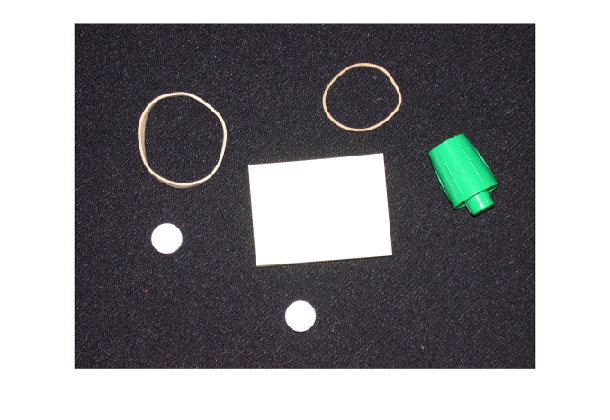

RGB = imread('pillsetc.png');
imshow(RGB);

2) Umbraliza la imagen

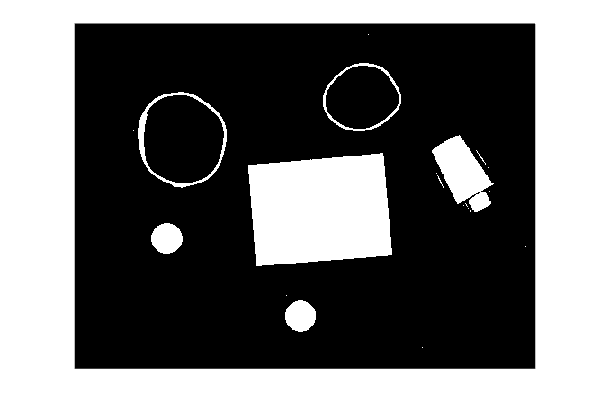

I = rgb2gray(RGB);
bw = imbinarize(I);
imshow(bw)

3) Elimina el ruido

Usando operaciones morfológicas se eliminan los píxeles que no pertenecen a los objetos de interés.

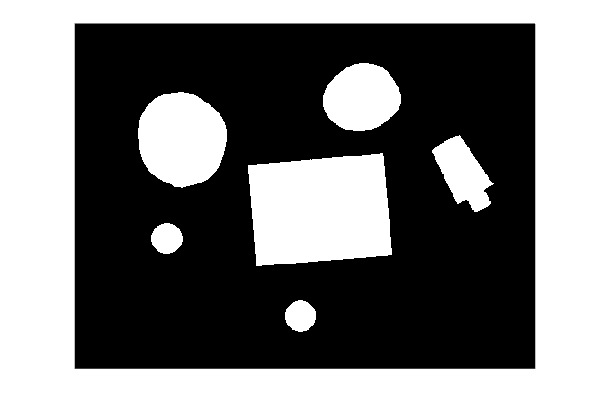

% remove all object containing fewer than 30 pixels
bw = bwareaopen(bw,30);

% fill a gap in the pen's cap
se = strel('disk',2);
bw = imclose(bw,se);

% fill any holes, so that regionprops can be used to estimate
% the area enclosed by each of the boundaries
bw = imfill(bw,'holes');

imshow(bw)

4) Encuentra los contornos

Nos centramos sólo en los límites exteriores. La opción `'noholes' `acelerará el proceso al evitar que la función `bwboundaries` busque contornos internos. 

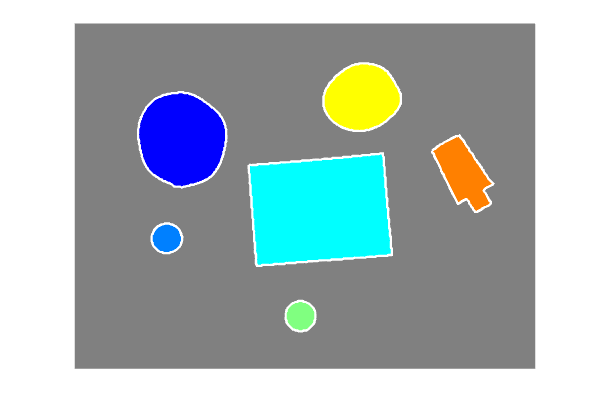

[B,L,n,A] = bwboundaries(bw,'noholes'); % Returns B, a cell array of boundary pixel locations, and matrix L where objects and holes are labeled..

% Display the label matrix 
imshow(label2rgb(L, @jet, [.5 .5 .5]))

hold on  % to draw the next in the same figure

% draws the boundaries of each object.
for k = 1:n
  boundary = B{k};
  plot(boundary(:,2), boundary(:,1), 'w', 'LineWidth', 2)
end

Se pide:

- Utilice la ayuda de Matlab para conseguir información sobre la función `regionprops `(parámetros requeridos, propiedades que calcula, etc.).

help regionprops

 regionprops - Measure properties of image regions
    The regionprops function measures properties such as area, centroid, and
    bounding box, for each object (connected component) in an image.

    Syntax
      stats = regionprops(BW,properties)
      stats = regionprops(CC,properties)
      stats = regionprops(L,properties)
      stats = regionprops(regions,I,properties)
      stats = regionprops(outputFormat,___)

    Input Arguments
      BW - Binary image
        logical array
      CC - Connected components
        structure
      L - Label image
        numeric array 

doc regionprops

- Usando dicha función, calcule el área, el perímetro y la circularidad de cada objeto de la imagen previa. 

% Imagen utilizada
figure, imshow(bw);

% Area de los objetos
area = regionprops(bw, 'area')

area = 6×1 struct array with fields:
    Area


% Perimetro de los objetos
perimetro = regionprops(bw, 'Perimeter')

perimetro = 6×1 struct array with fields:
    Perimeter


% Circularidad de los objetos
circularidad = regionprops(bw, 'Circularity')

circularidad = 6×1 struct array with fields:
    Circularity


- Umbralizando el valor de la circularidad, resalte los objetos que sean aproximadamente circulares (p.ej., pintando las boundaries de color diferente). Puede utilizar un slidebar para verificar la influencia del valor del umbral en el conjunto de objetos resaltados.

% Establecemos un umbral
umbral = 0.99;

% Obtenemos los objetos circulares
idx_circulos = find([circularidad.Circularity] > umbral)

idx_circulos =      2     4


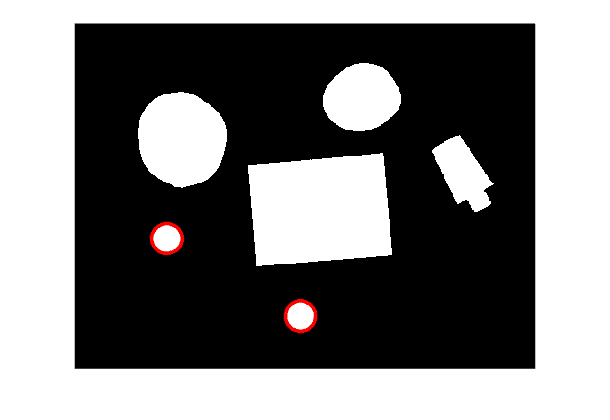

% Display the label matrix 
imshow(bw)
hold on

% draws the boundaries of each object.
for k = idx_circulos
  boundary = B{k};
  plot(boundary(:,2), boundary(:,1), 'r', 'LineWidth', 3)
end

- Cargue la imagen `'google.jpg'``,` rellene los agujeros internos de las letras con la función imfill(bw,'holes') y determine, calculando a partir de parámetros obtenidos con la función `regionprops`, si los objetos son cóncavos o convexos. Resalte con diferente color los objetos cóncavos y los convexos, utilizando el borde del objeto convexo ('ConvexHull'). Nota: En esta pregunta hay que tener en cuenta que el primer plano es oscuro y el fondo claro, por lo que hay que modificar los pasos 2 y 3 para obtener un etiquetado correcto. 

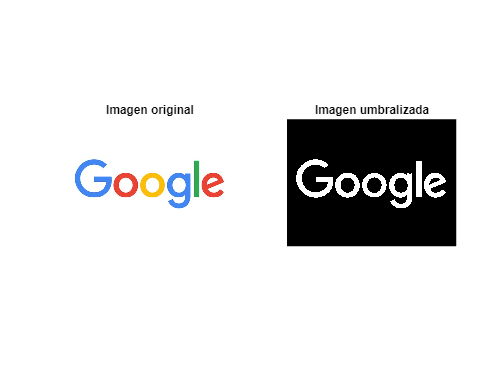

% Cargamos la imagen
I = imread('./Imagenes/google.jpg');

% Umbralizamos la imagen
bw = 1 - imbinarize(rgb2gray(I));

figure, 
subplot(1,2,1), imshow(I); title('Imagen original');
subplot(1,2,2), imshow(bw); title('Imagen umbralizada');

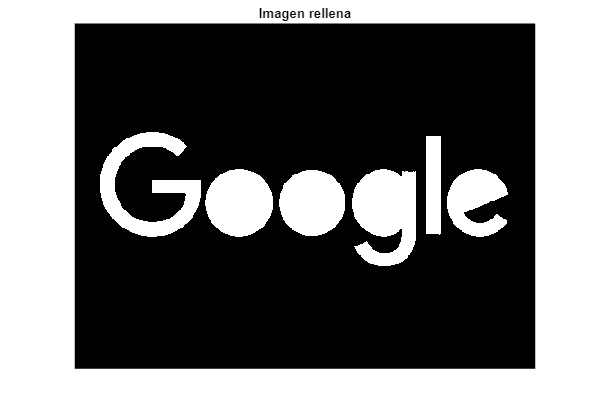

% Rellenamos los agujeros de las letras
bw = imfill(bw, "holes");
figure, imshow(bw); title('Imagen rellena');

% Obtenemos la concavidad
conc = regionprops(bw, 'ConvexHull').ConvexHull

conc =    43.0000  140.5000
   42.5000  141.0000
   38.5000  146.0000
   36.5000  149.0000
   35.5000  151.0000
   34.5000  153.0000
   33.5000  155.0000
   32.5000  157.0000
   31.5000  159.0000
   30.5000  162.0000


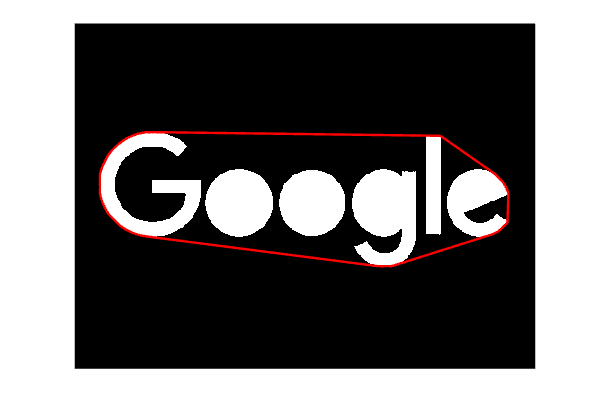

% Mostramos los resultados
figure, imshow(bw);
hold on;

for i = 1:length(conc)
    plot(conc(:, 1), conc(:, 2), 'r', 'LineWidth', 2);
end